clear
clc
close all

# Plot

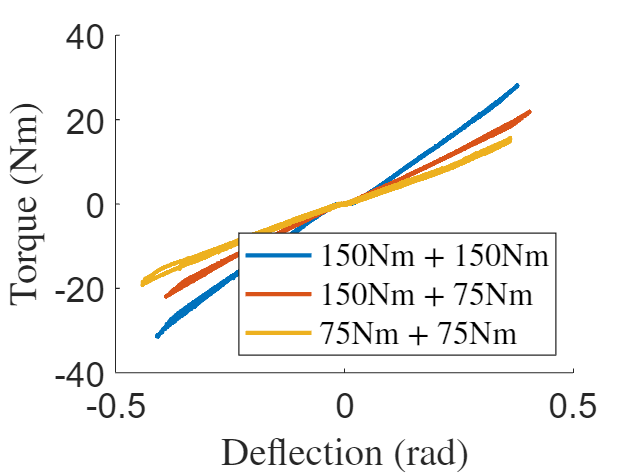

data_1 = readmatrix("150Nm+150Nm\defl_torque.csv");
shift_1 = readmatrix("150Nm+150Nm\Shift.csv");
model_1 = readmatrix("150Nm+150Nm\Logit_Model_Params.csv");
data_2 = readmatrix("150Nm+75Nm\defl_torque.csv");
shift_2 = readmatrix("150Nm+75Nm\Shift.csv");
model_2 = readmatrix("150Nm+75Nm\Logit_Model_Params.csv");
data_3 = readmatrix("75Nm+75Nm\defl_torque.csv");
shift_3 = readmatrix("75Nm+75Nm\Shift.csv");
model_3 = readmatrix("75Nm+75Nm\Logit_Model_Params.csv");

figure; 
hold on

plot((data_1(:, 1)) .* pi ./ 180 - shift_1(1), data_1(:, 2) - shift_1(2), ...
    LineWidth=2, DisplayName="150Nm + 150Nm")
plot((data_2(:, 1)) .* pi ./ 180 - shift_2(1), data_2(:, 2) - shift_2(2), ...
    LineWidth=2, DisplayName="150Nm + 75Nm")
plot((data_3(:, 1)) .* pi ./ 180 - shift_3(1), data_3(:, 2) - shift_3(2), ...
    LineWidth=2, DisplayName="75Nm + 75Nm")
hold off
legend(Location="southeast", Interpreter="latex")
xlabel("Deflection (rad)", Interpreter="latex")
ylabel("Torque (Nm)", Interpreter="latex")
set(gca, "fontsize", 16)